## Convolution and deconvolution: an Illustration

This live script visualizes some of the elements of convolution and deconvolution

1) Convolution: a simple mathematical function that quantifies the similarity between a pattern (a "kernel") such as the red square wave below with data (the blue rectangularish thingy below). The convolution (black line) reflects how similar the blue signal is with the kernel at any given time point. Convolution is thus used in all of digital signal processing. 

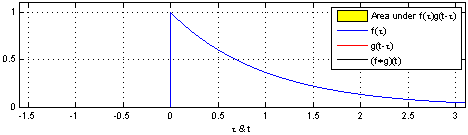

The math is simple. We take the kernel, move it to the first portion of the data by lining it up with the first sample point, then we multiply each element of the kernel with the data, sum the results into one new number and write that to that first sample point. This is the dot-product. 

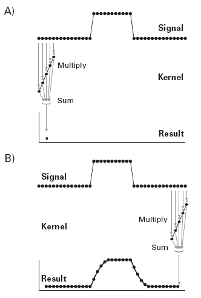

Convolution in signal generation and in fMRI research. 

if we want to generate a signal where a certain pattern (the kernel) occurs at certain times, we can use convolution to achieve that. Thus, programs liek SPM use convolution of stimulus timinng info with a lernel that resembles the typical BOLD (fMRI) response  as the kernel to generate fake, ideal, fMRI activation for comparison/correlation with the real data: 

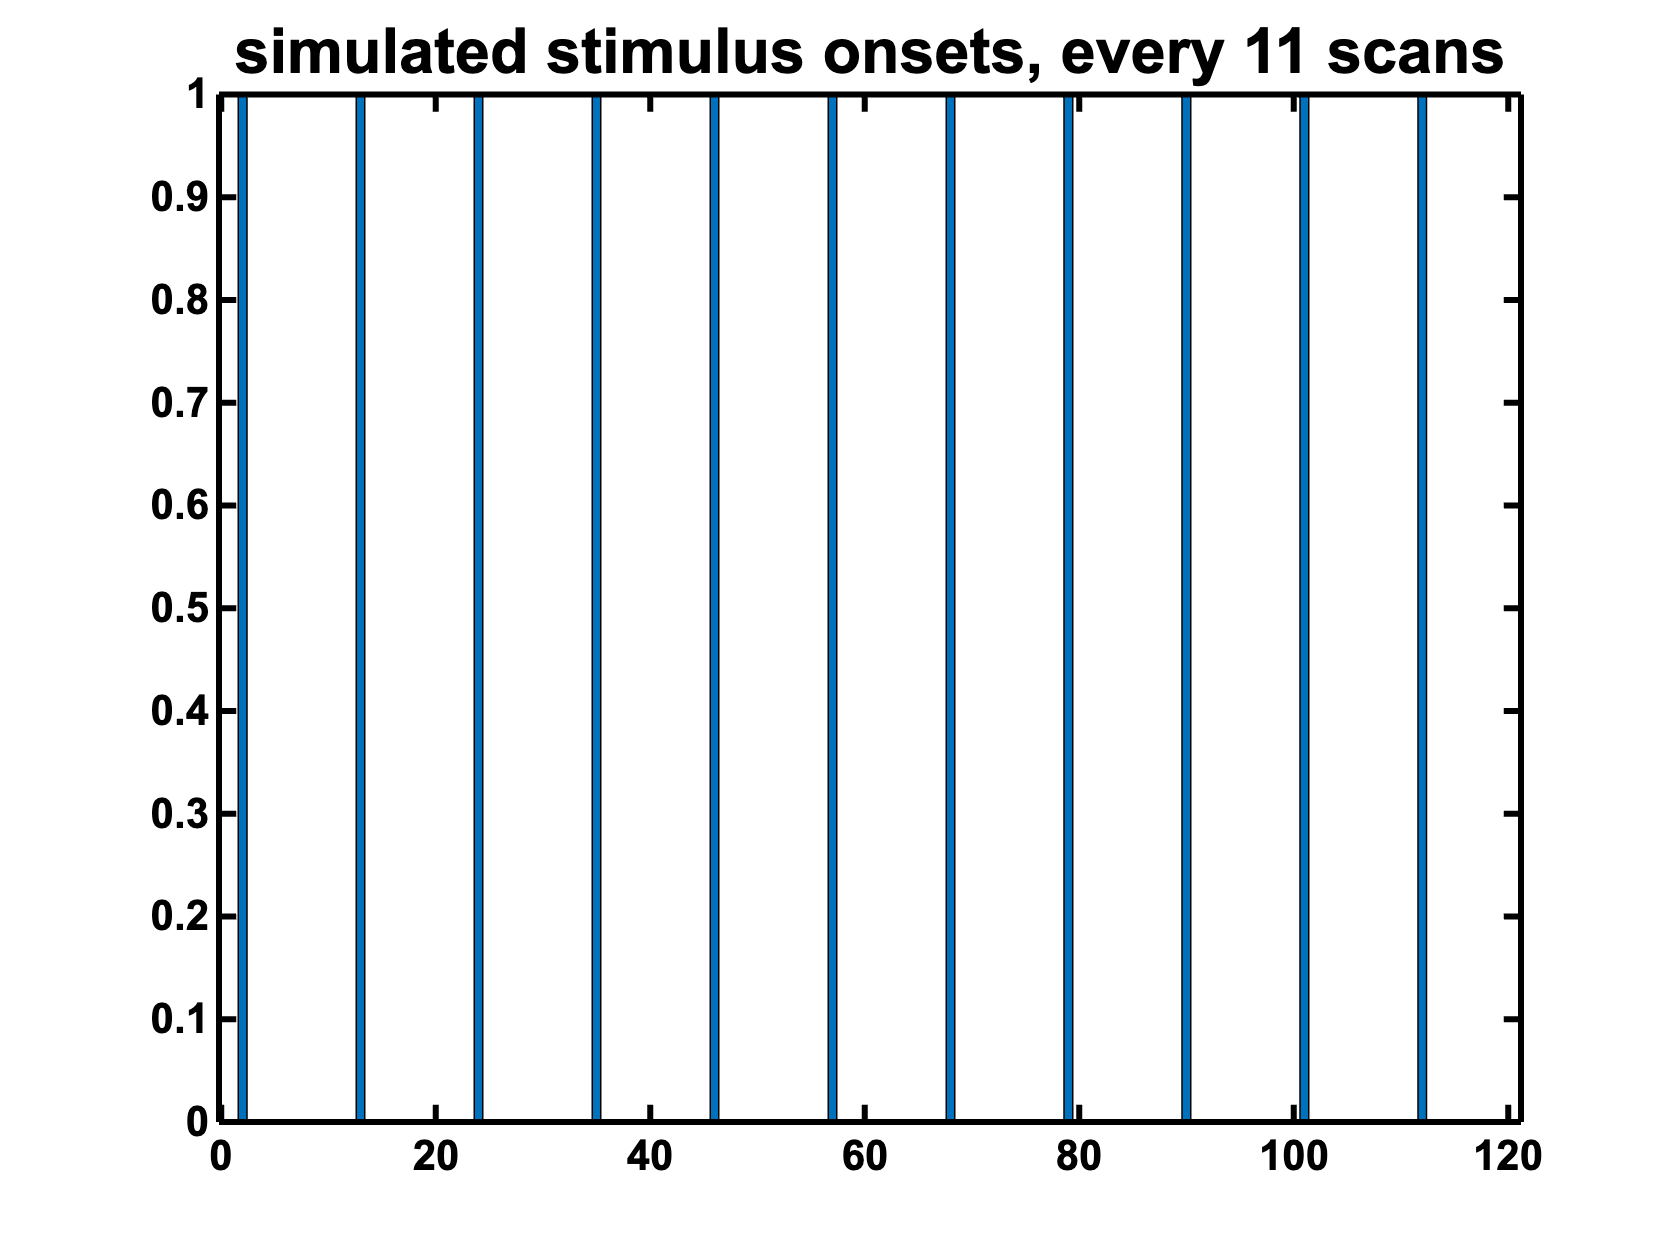

%First, make onsets for 120 MR images. 
onsets = zeros(1, 120); 
onsets(2:11:end) = 1; %simple case where a stimulus is on every 11 scans
bar(onsets), title ('simulated stimulus onsets, every 11 scans')

% now we make a kernel
% the inverted gamma function is nice because it looks like fMRI in V1
% let's make one that is 10 scans long
kernel = (1./gamma(0.1:0.5:5))

kernel =     0.1051    0.6715    1.0511    1.1192    0.9556    0.6995    0.4550    0.2690    0.1468    0.0747


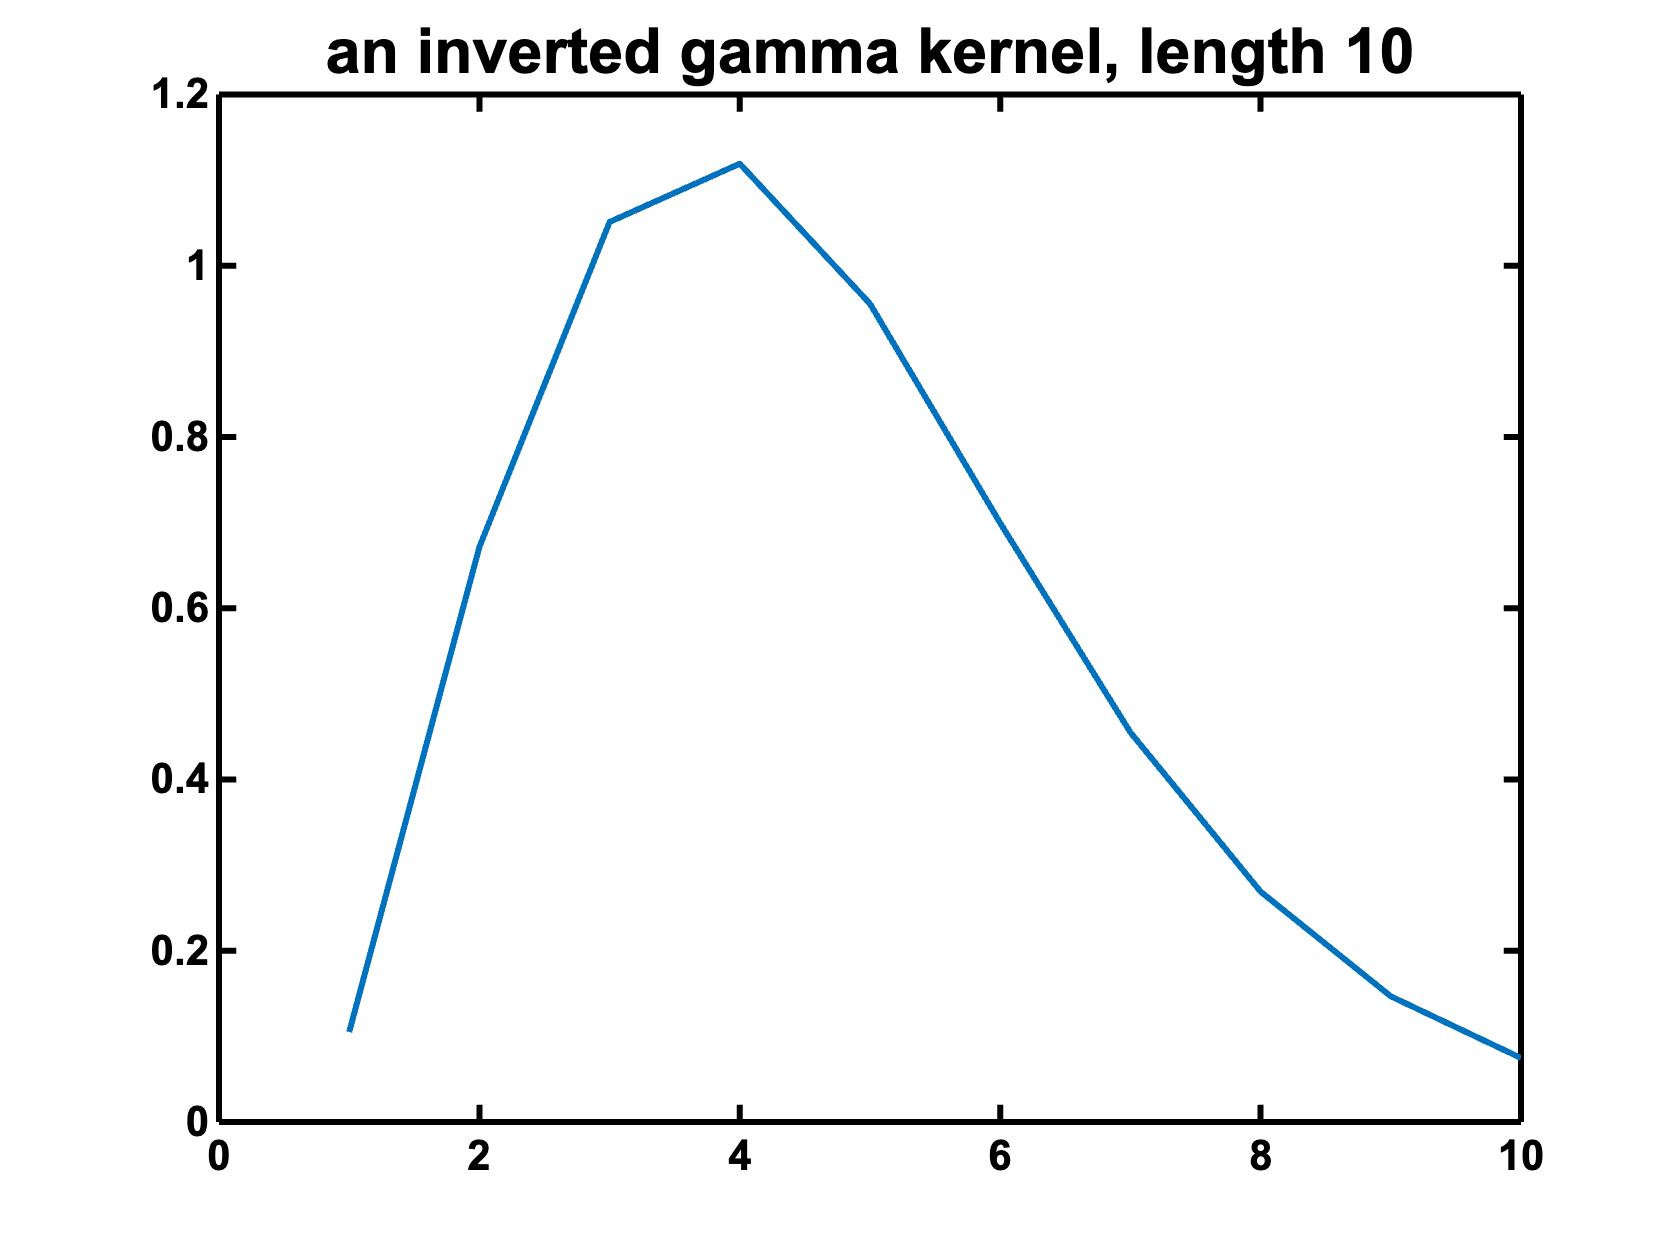

figure
plot(1./gamma(0.1:0.5:5)), title('an inverted gamma kernel, length 10')

Now we just convolve the onsets with the kernel and plot the result

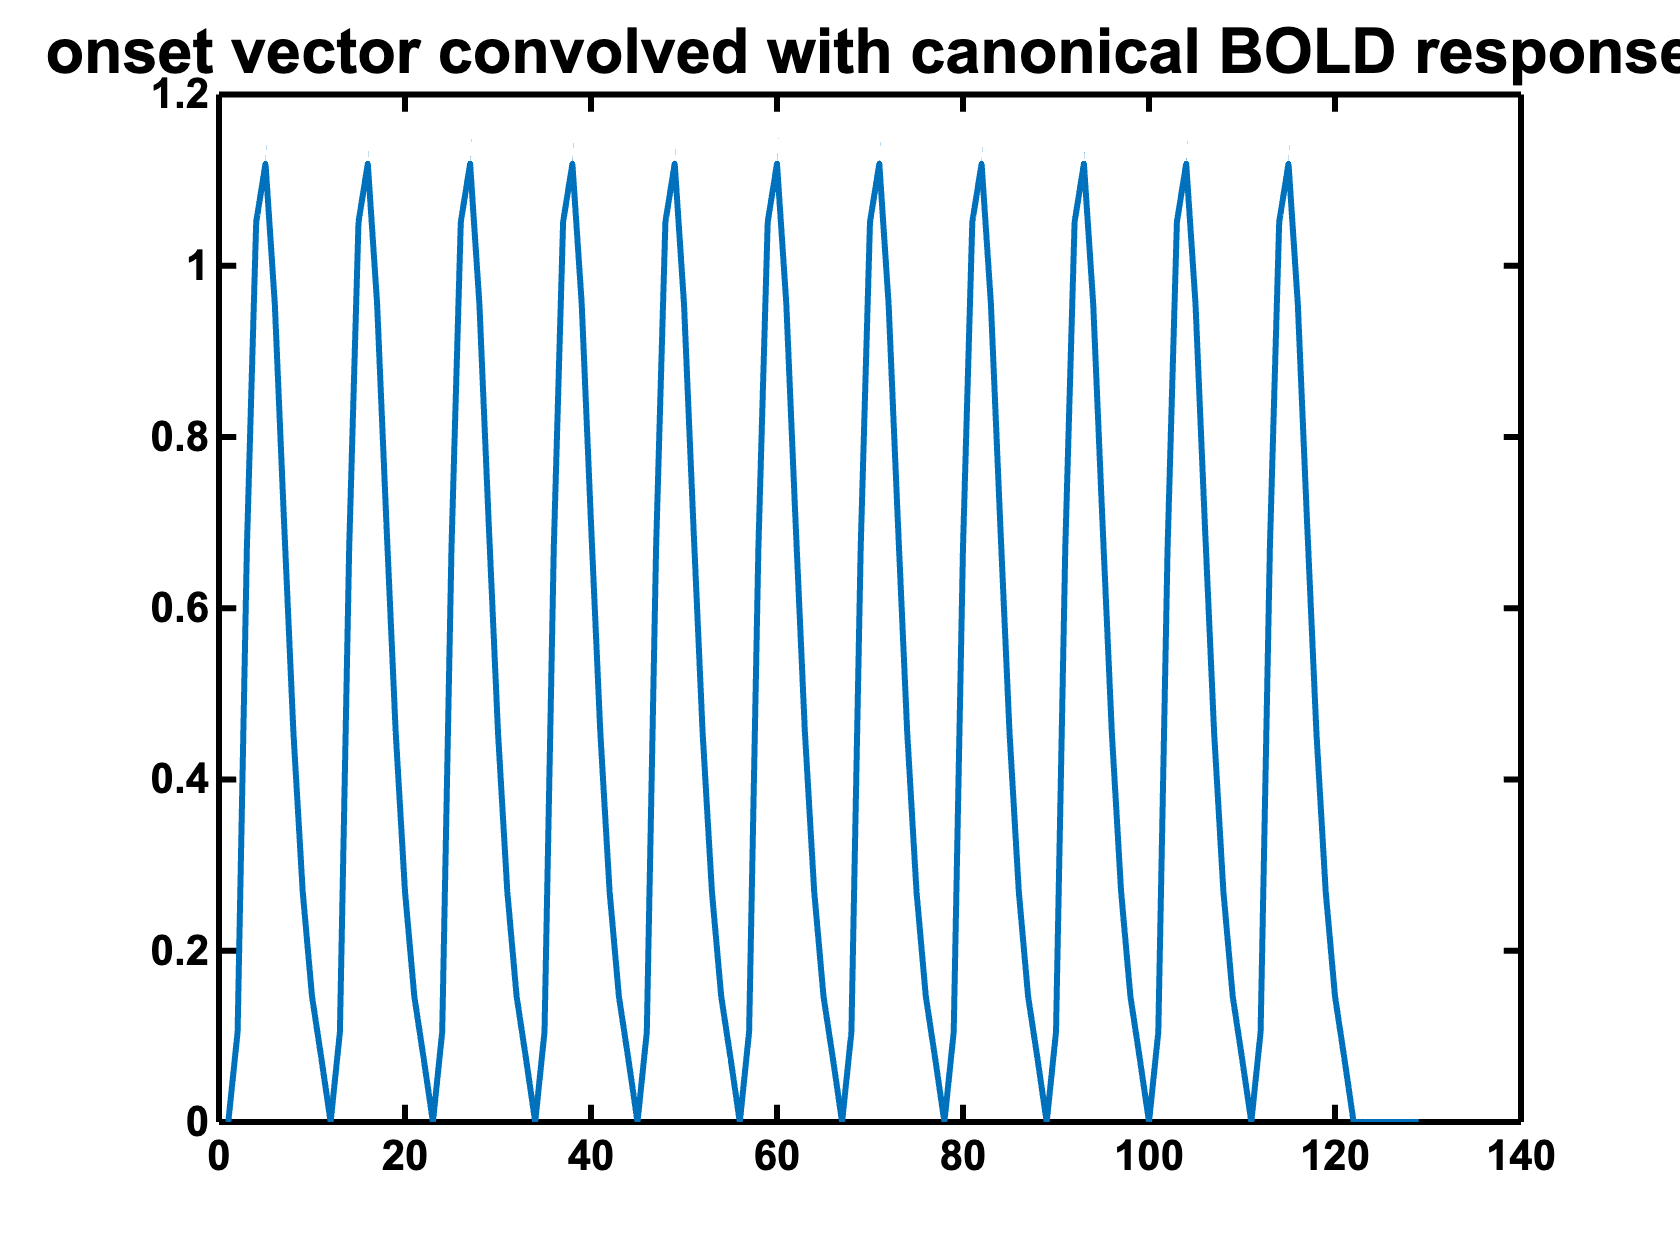

convolution  = conv(onsets, kernel); 
figure
plot(convolution), title('onset vector convolved with canonical BOLD response')

So this basically puts each 10 second kernel at the location where the onset is. There were 11 seconds between onsets, so this is like copy paste, but how about when the kernel is longer than the interval between onsets? 

kernel = (1./gamma(0.1:0.25:5)) % this Kernel is twice as long

kernel =     0.1051    0.3928    0.6715    0.8989    1.0511    1.1221    1.1192    1.0575    0.9556    0.8312    0.6995    0.5716    0.4550    0.3537    0.2690    0.2006    0.1468    0.1056    0.0747    0.0521


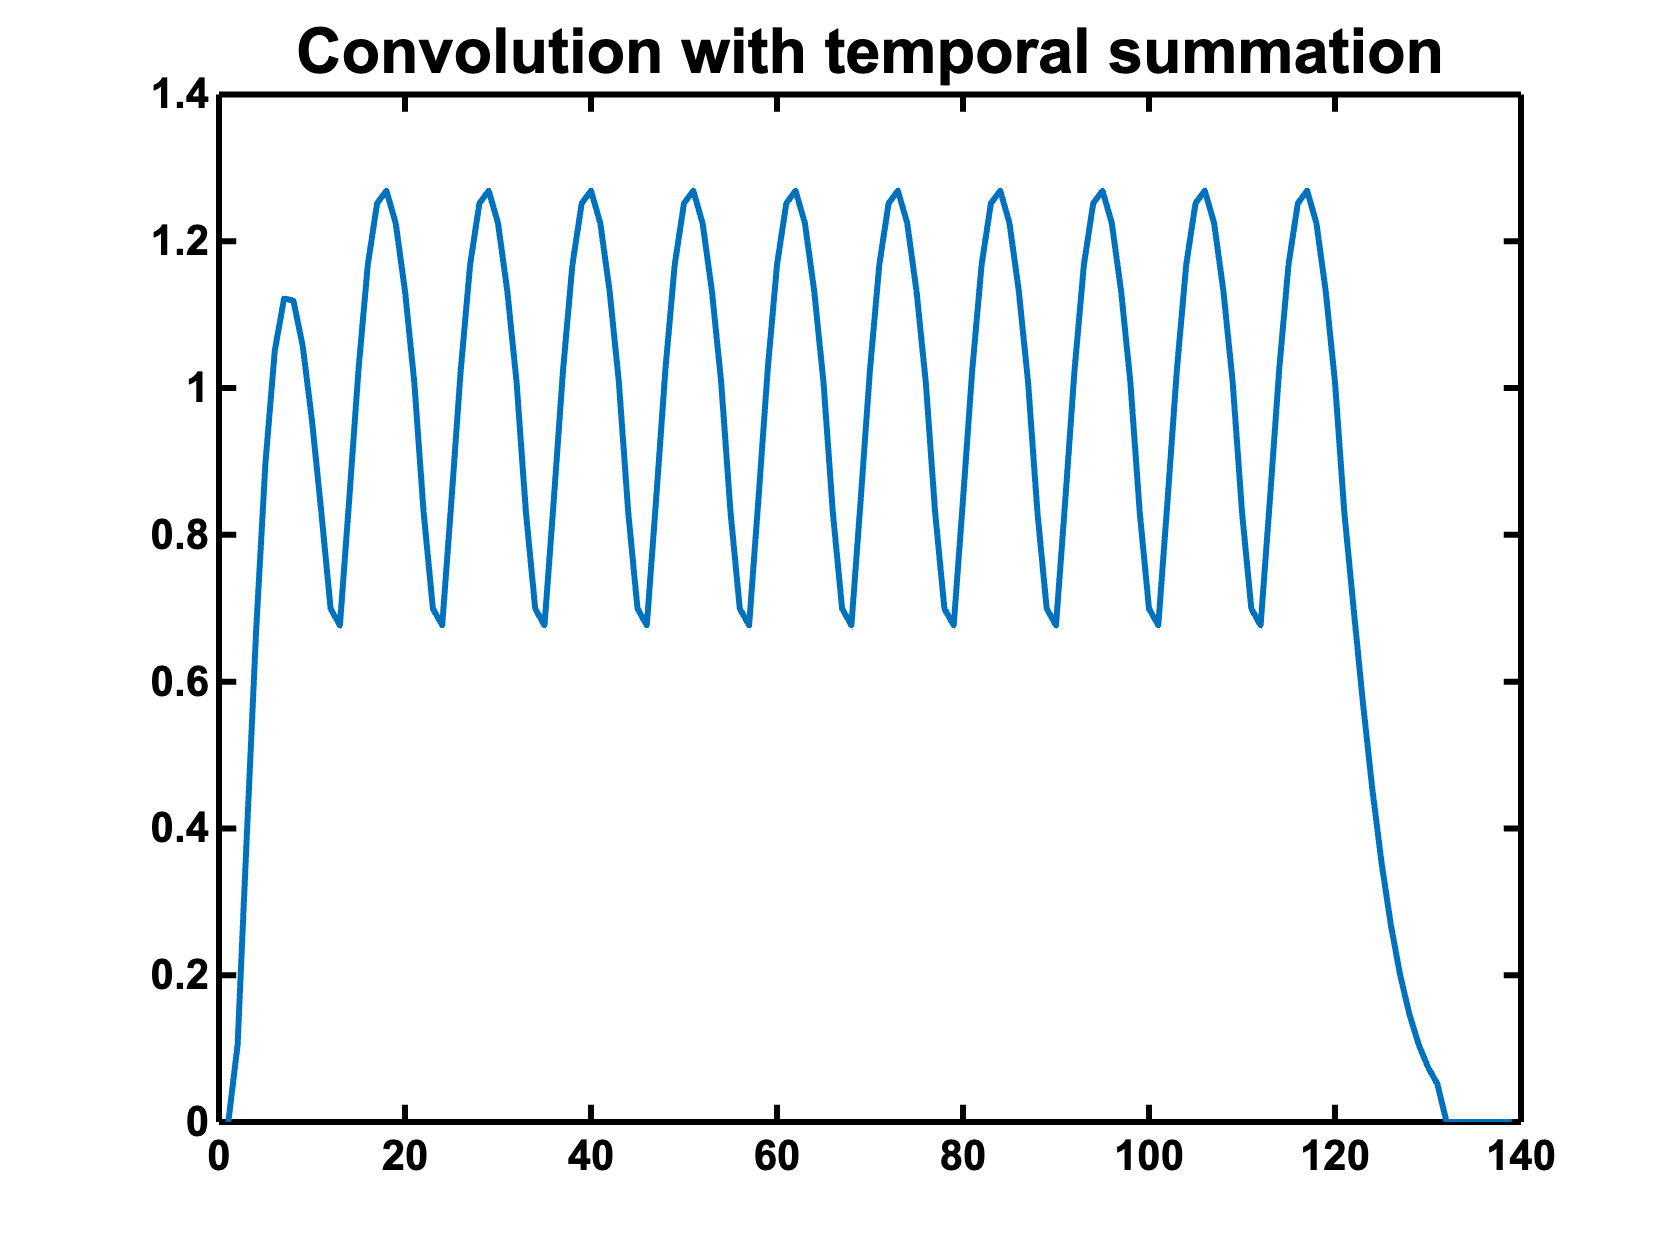

convolution  = conv(onsets, kernel); 
figure
plot(convolution), title('Convolution with temporal summation')

When the convolution encounters overlap, then temporal summation results, because convolution is a process of shifting the kernel, multiplying element-wise, and summation to one new value, rinse and repeat. Because of the shifting and summing up portion of the algorithm, if the Kernel spans multiple, similar events, it will show temporal summation. 

 This is more interesting with variable inter-onset times. 

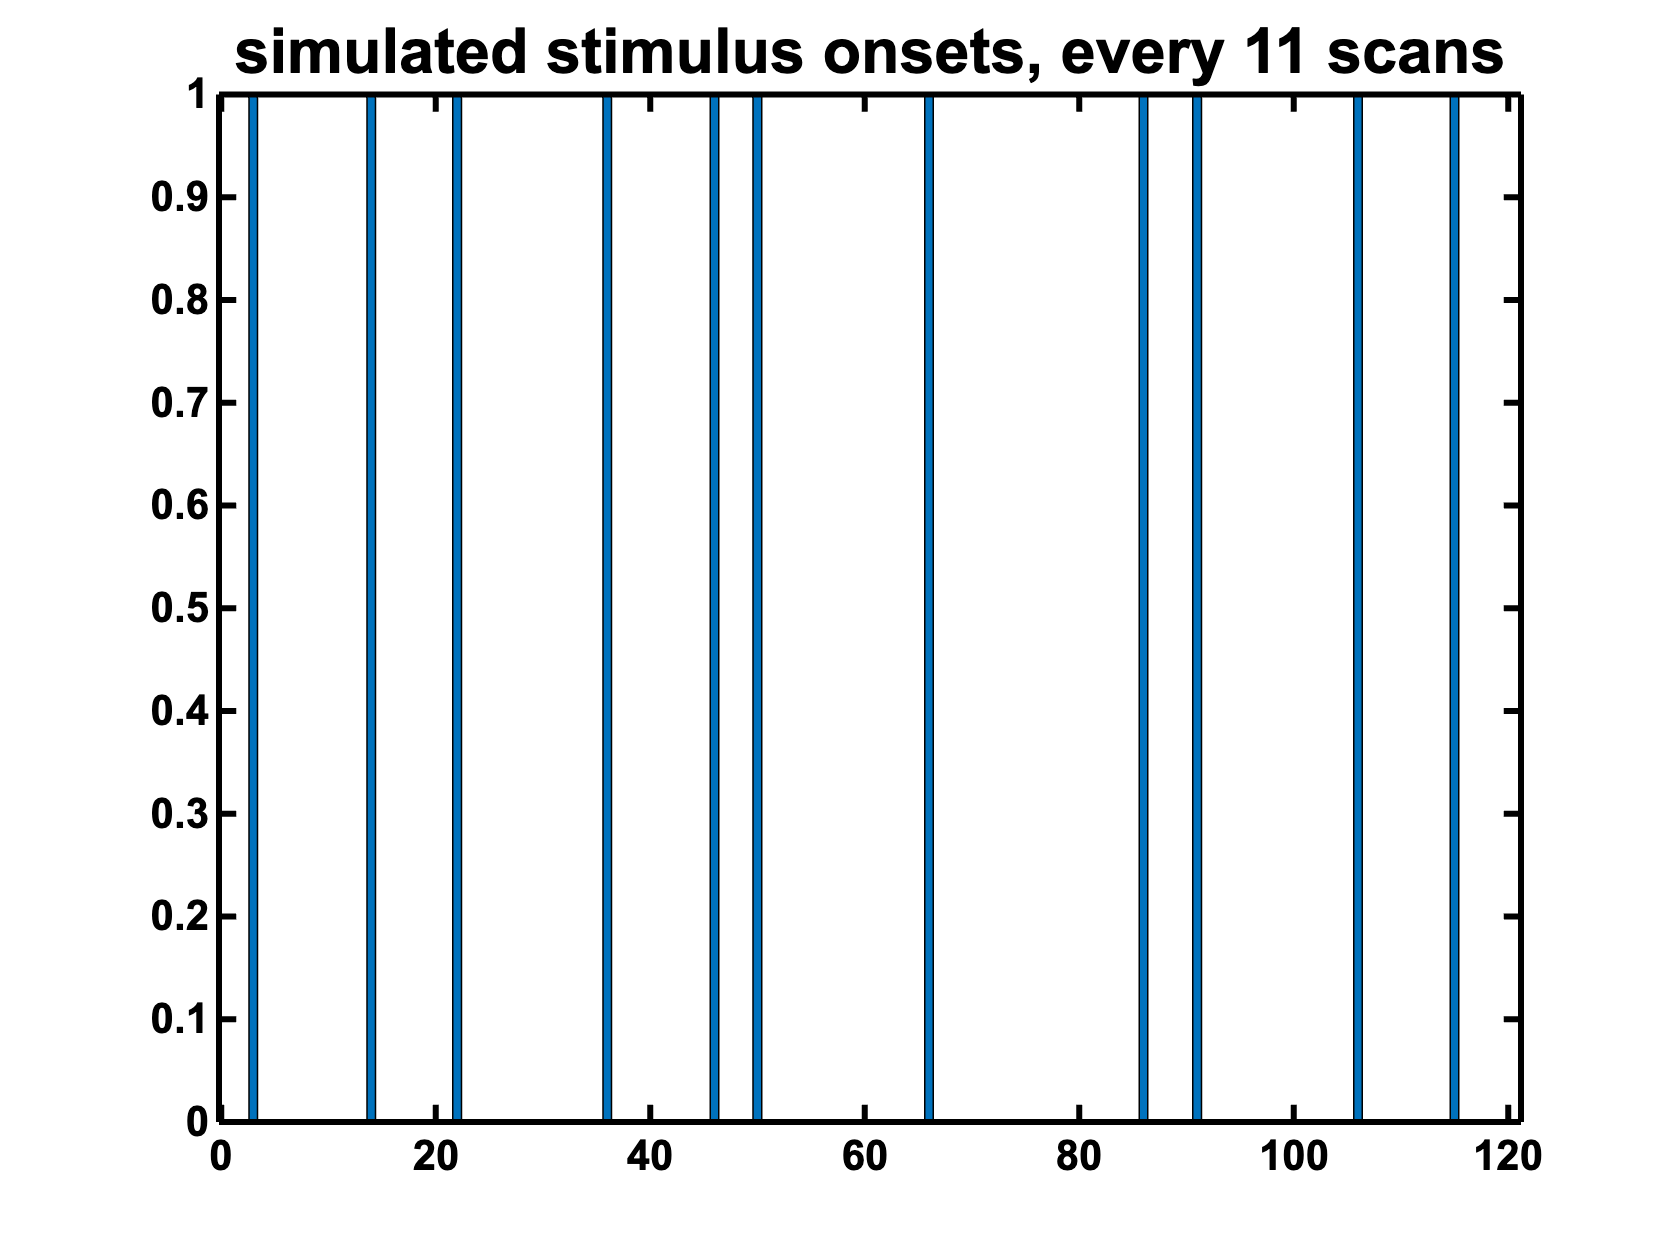

onsets = zeros(1, 120);
onsets([3 14 22 36 46 50 66 86 91 106 115]) = 1; %simple case where a stimulus is on every 11 scans
bar(onsets), title ('simulated stimulus onsets, every 11 scans')

Now we convolve these onset times with the same kernel

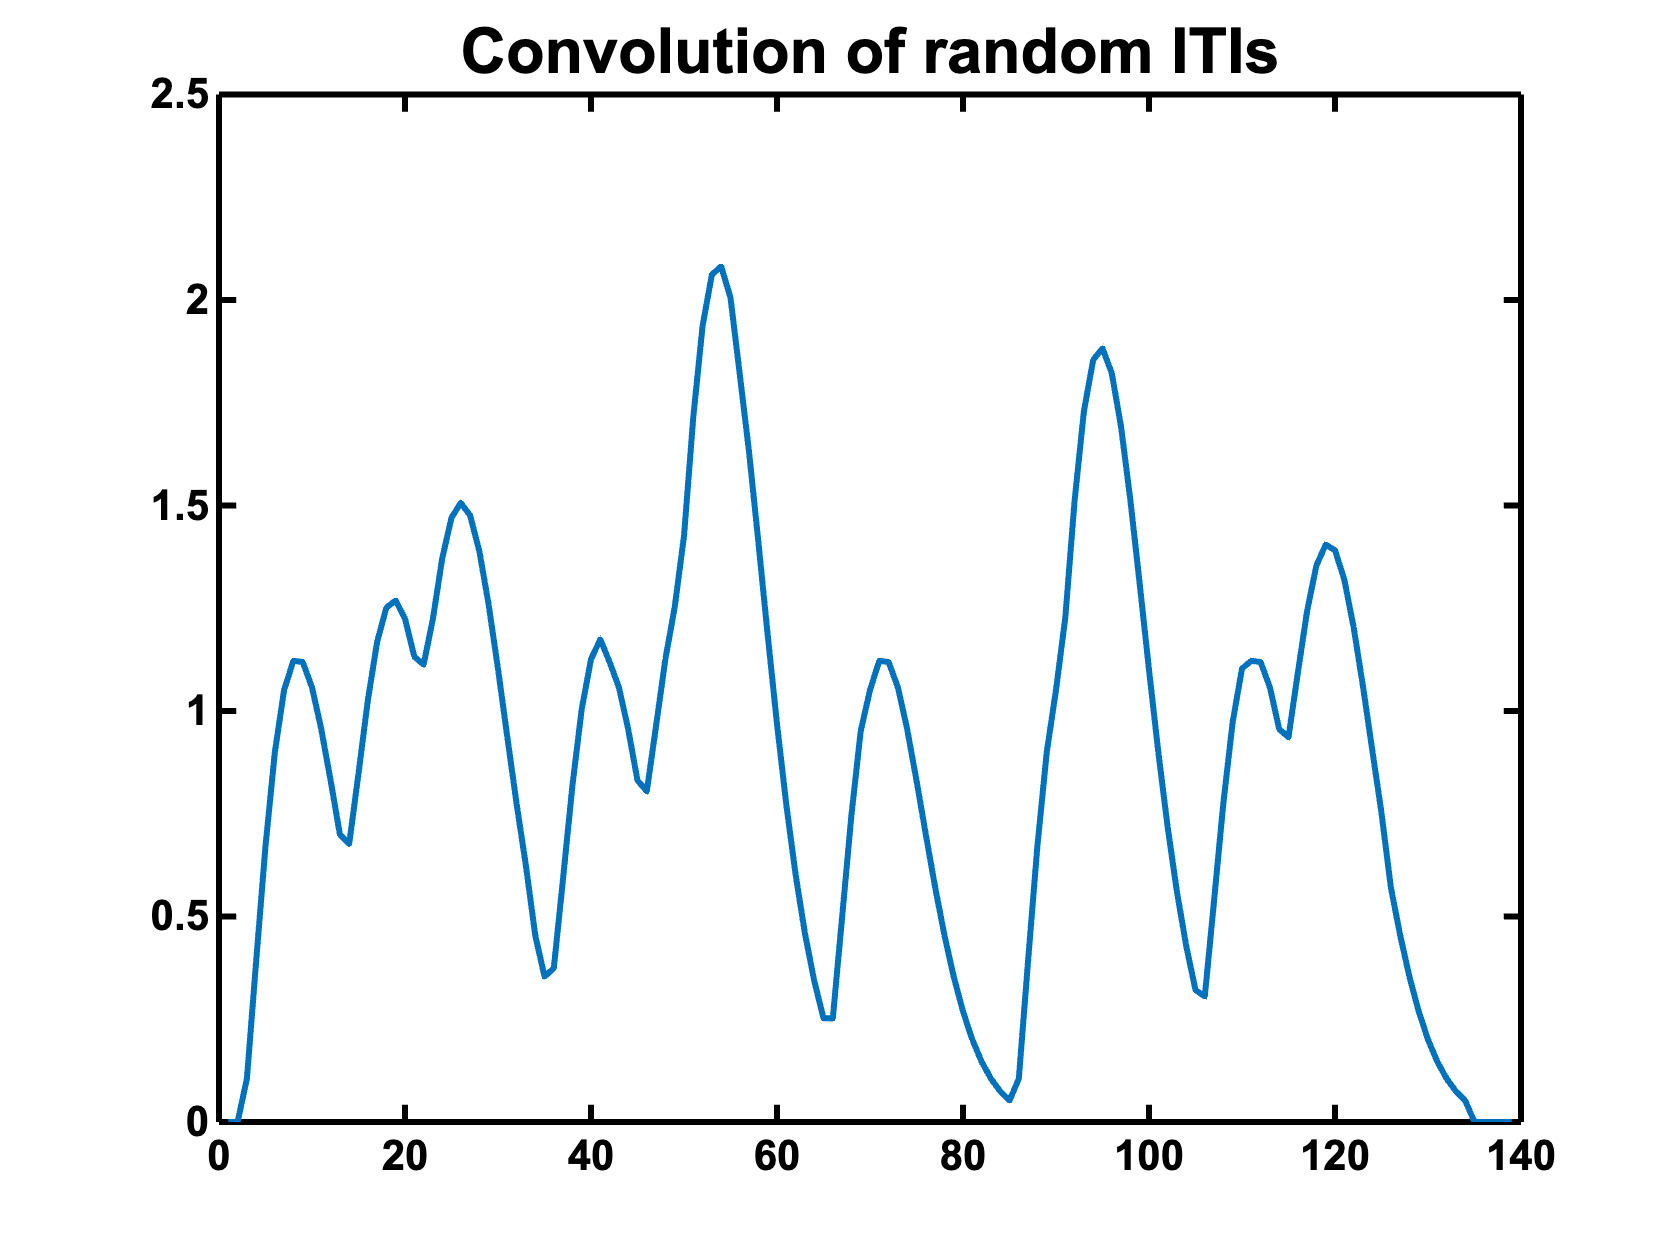

convolution  = conv(onsets, kernel); 
figure
plot(convolution), title('Convolution of random ITIs')

Longer intervals between onsets prompt complete reduction to baseline, temporal proximity prompts smeared, overlapping events. How about gamma-shaped responses to stimuli that are longer than one image? 

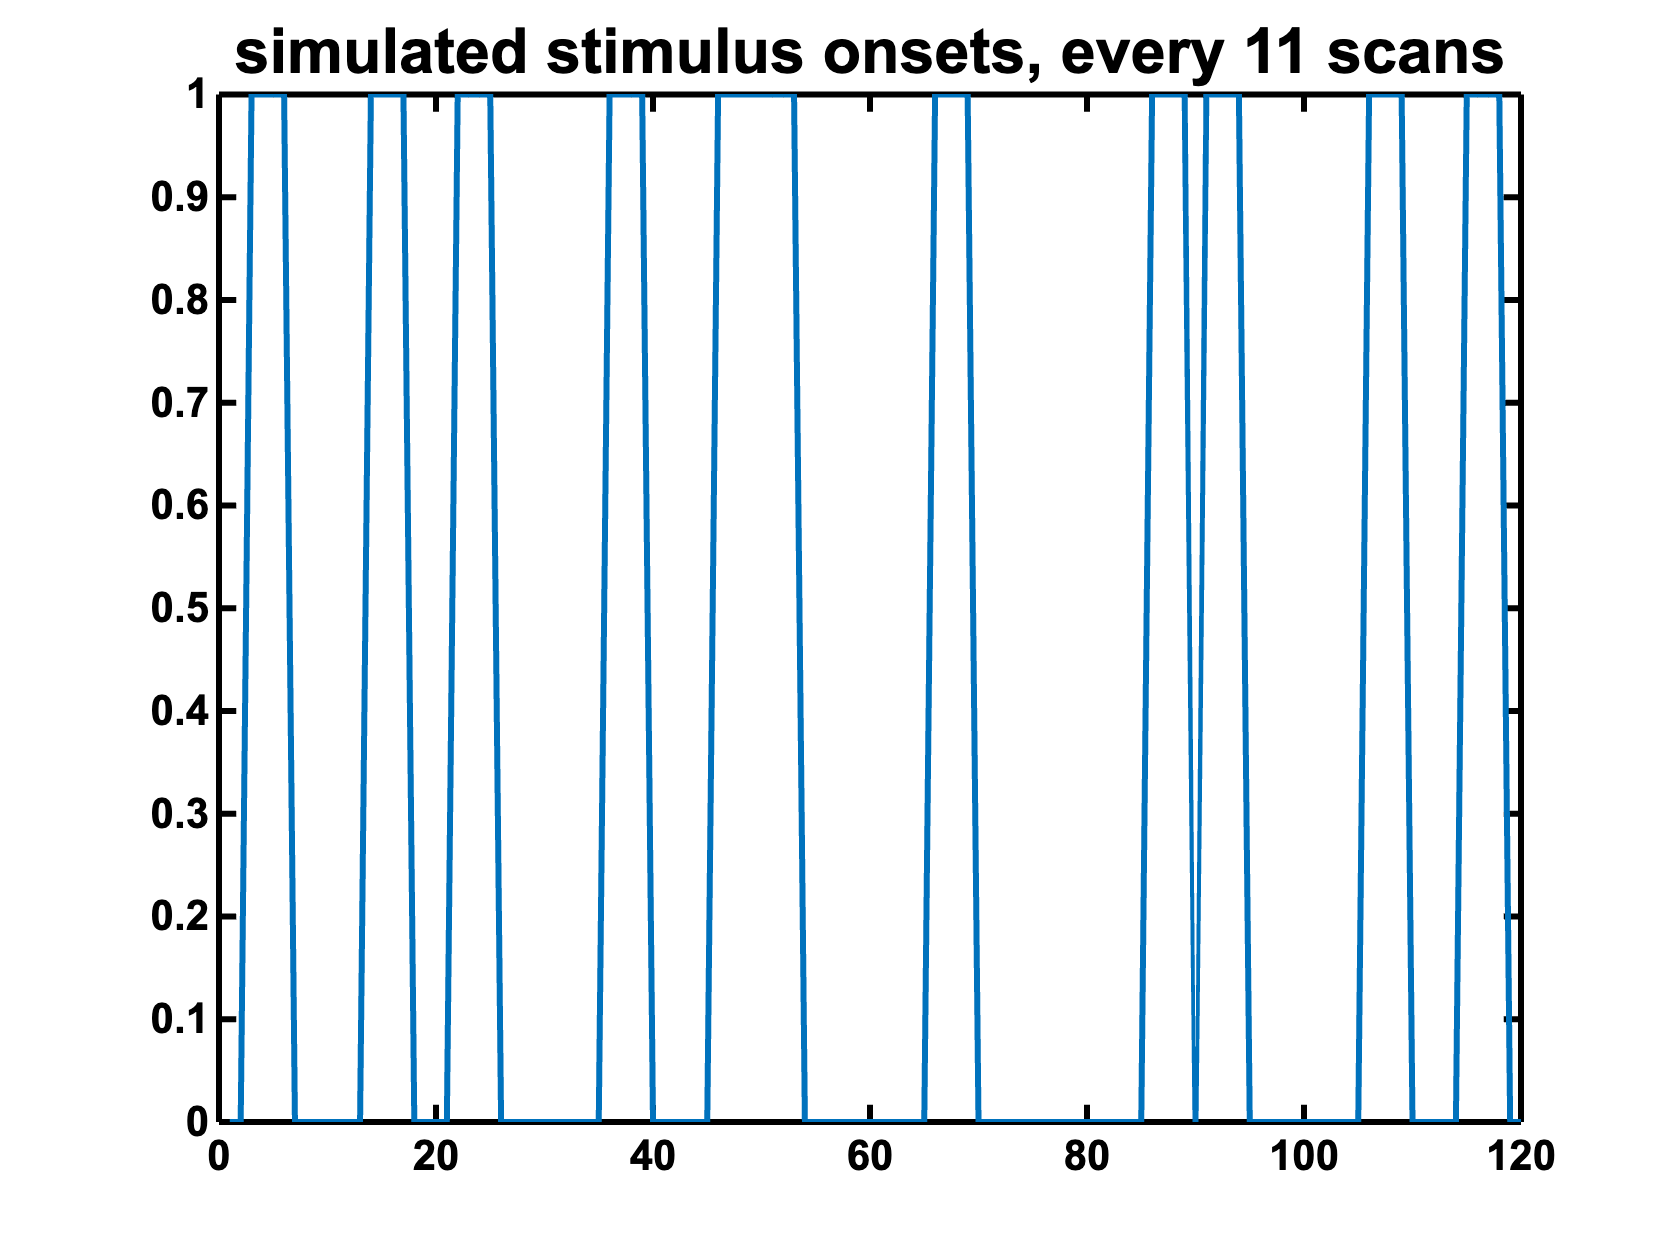

onsets = zeros(1, 120);
onsets([3 14 22 36 46 50 66 86 91 106 115]) = 1;%simple case where a stimulus is on every 11 scans
onsets([3 14 22 36 46 50 66 86 91 106 115]+1) = 1;
onsets([3 14 22 36 46 50 66 86 91 106 115]+2) = 1;
onsets([3 14 22 36 46 50 66 86 91 106 115]+3) = 1;
plot(onsets), title ('simulated stimulus onsets, every 11 scans')

Now we convolve these onset times with the same kernel

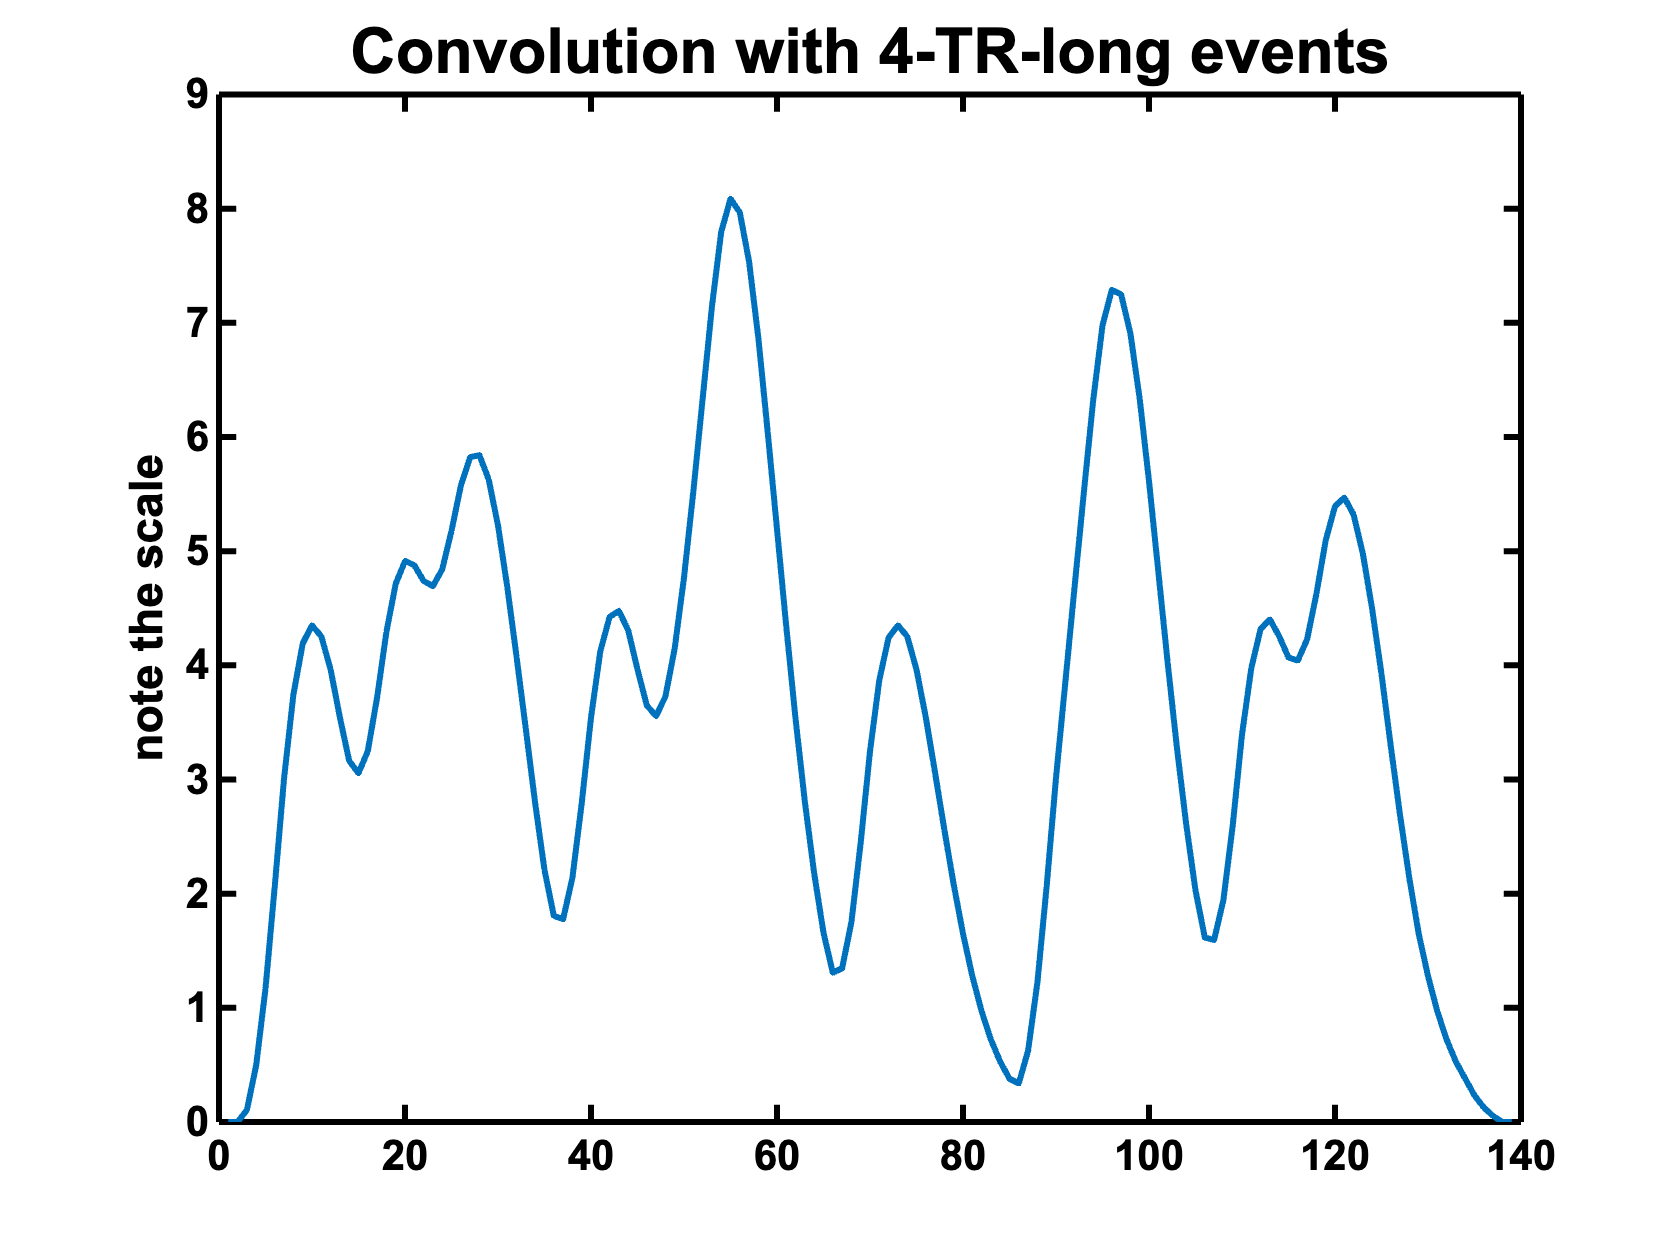

convolution  = conv(onsets, kernel); 
figure
plot(convolution), title('Convolution with 4-TR-long events'), ylabel('note the scale')

And now something completely different

## DEconvolution

deconvolution is the process where we wish to estimate the Kernel from known data and known event-times. This is a version of the so-called inverse problem , and we solve it with a regression. Let's start with the simulated we we have: 

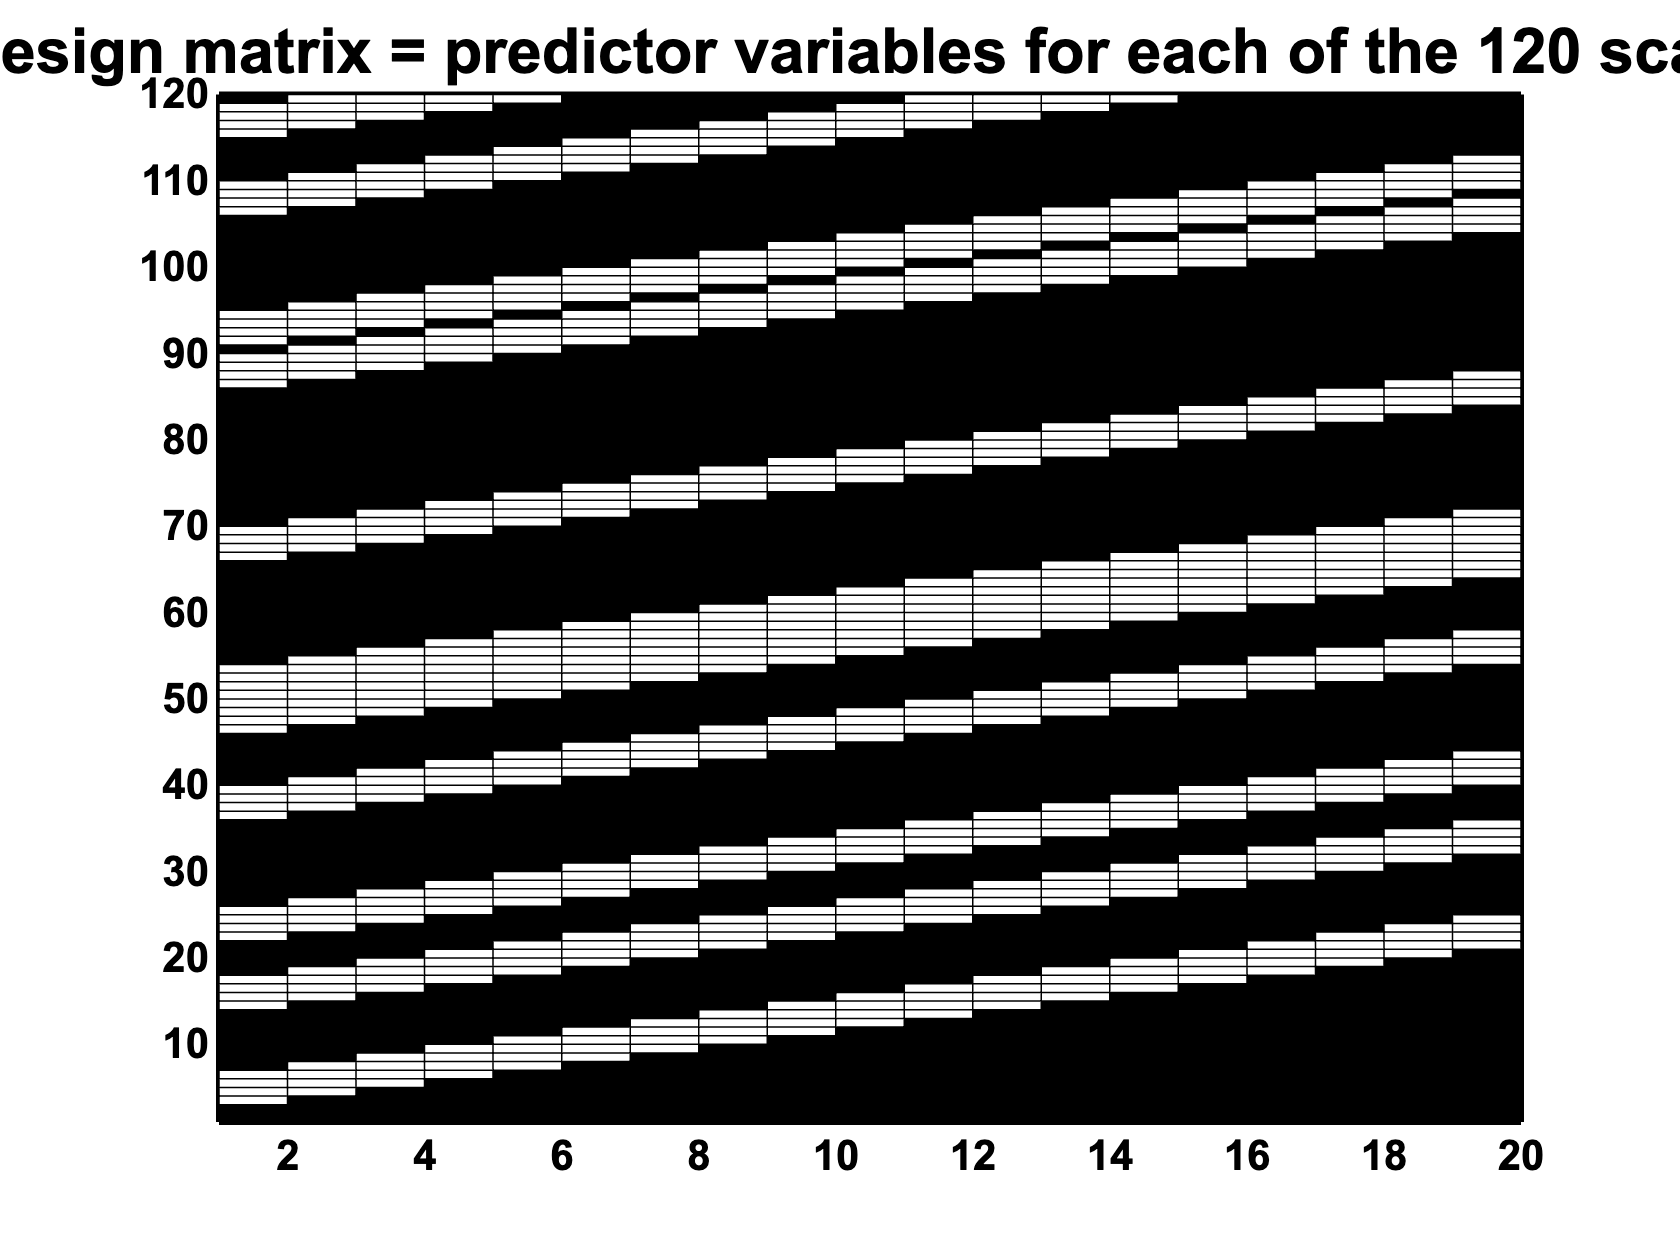

% for a regression, we need a "design matrix" X
X = zeros(length(convolution(1:120)), 20); % we know the convolution and the kernel we used had 20 values
temp = onsets';
for i=1:20
X(:,i) = temp;
temp = [0;temp(1:end-1)];
end
pcolor(X), colormap('gray'), title('design matrix = predictor variables for each of the 120 scans')

ans =     20   120


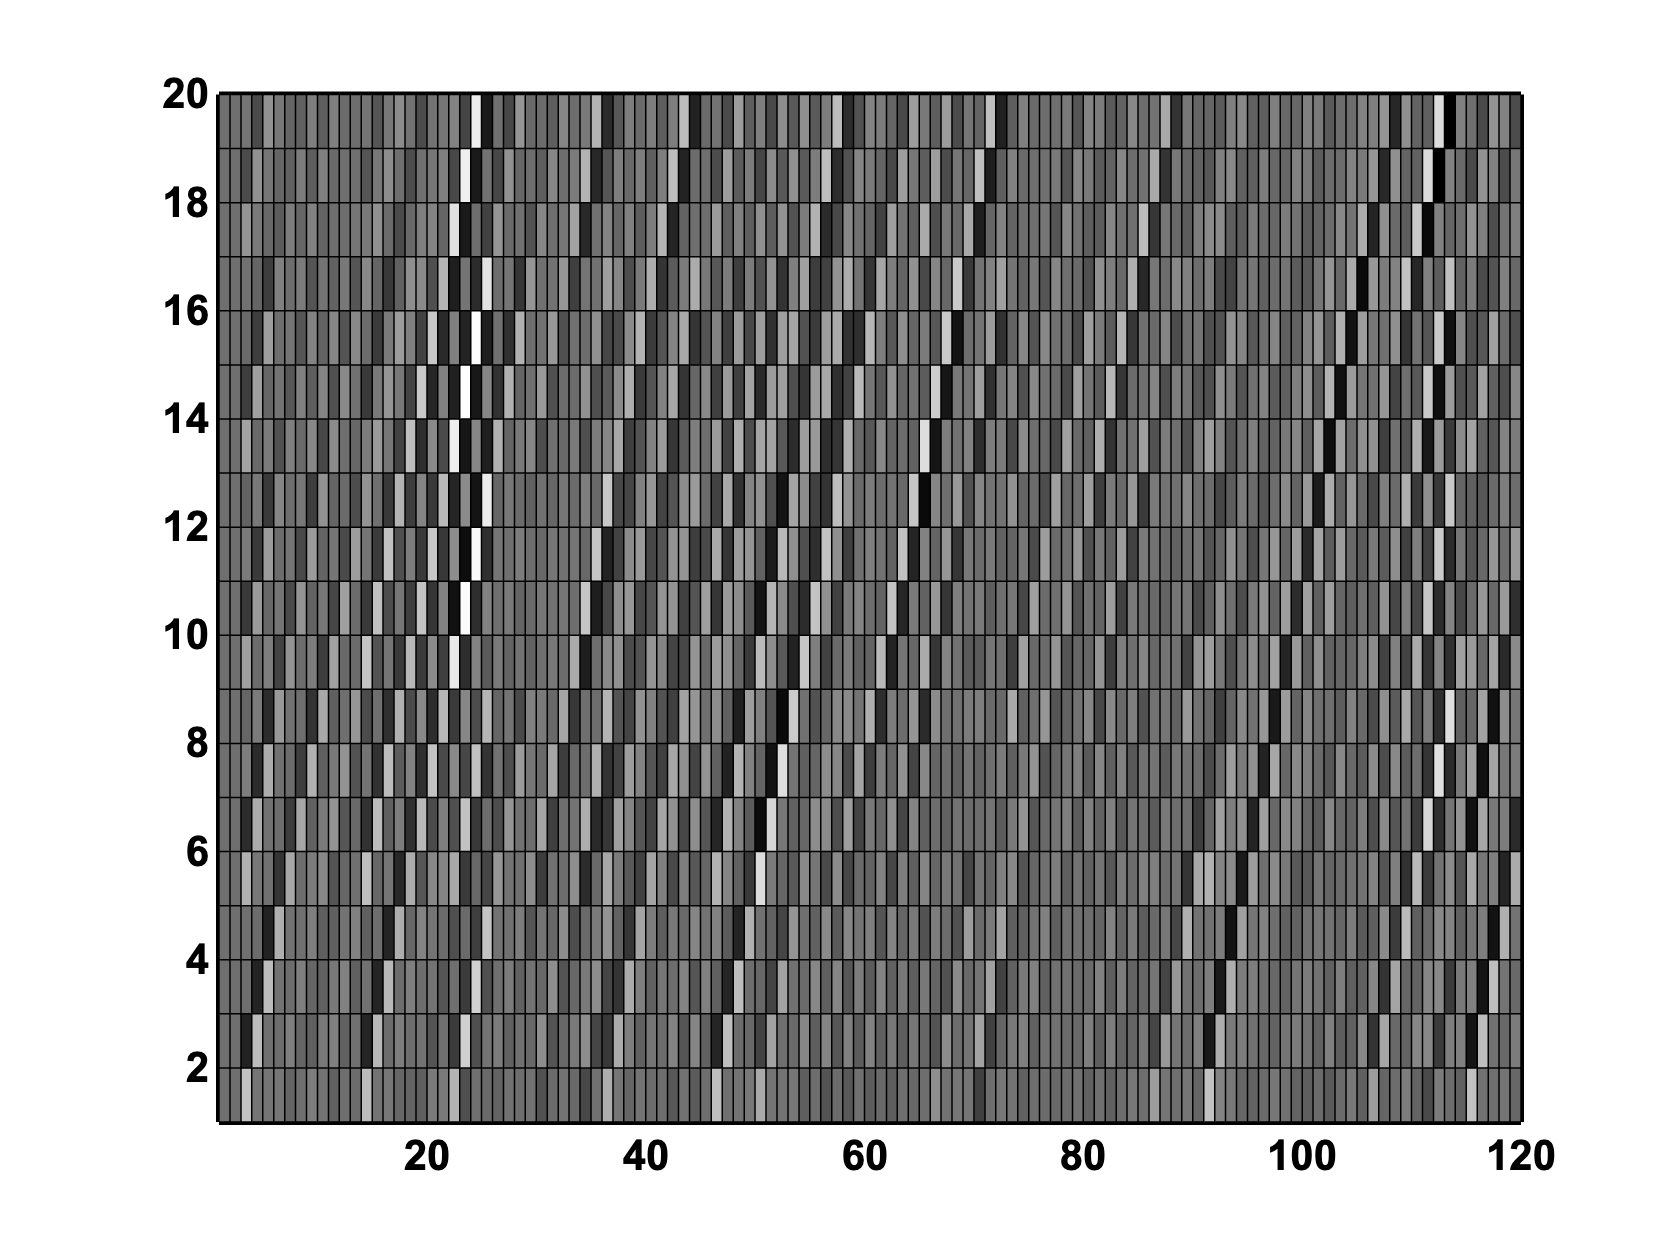


% now invert design matrix X
PX = pinv(X); size(PX), figure, pcolor(PX), colormap('gray')


% estimate kernel, h
h = PX* convolution(1:120)';

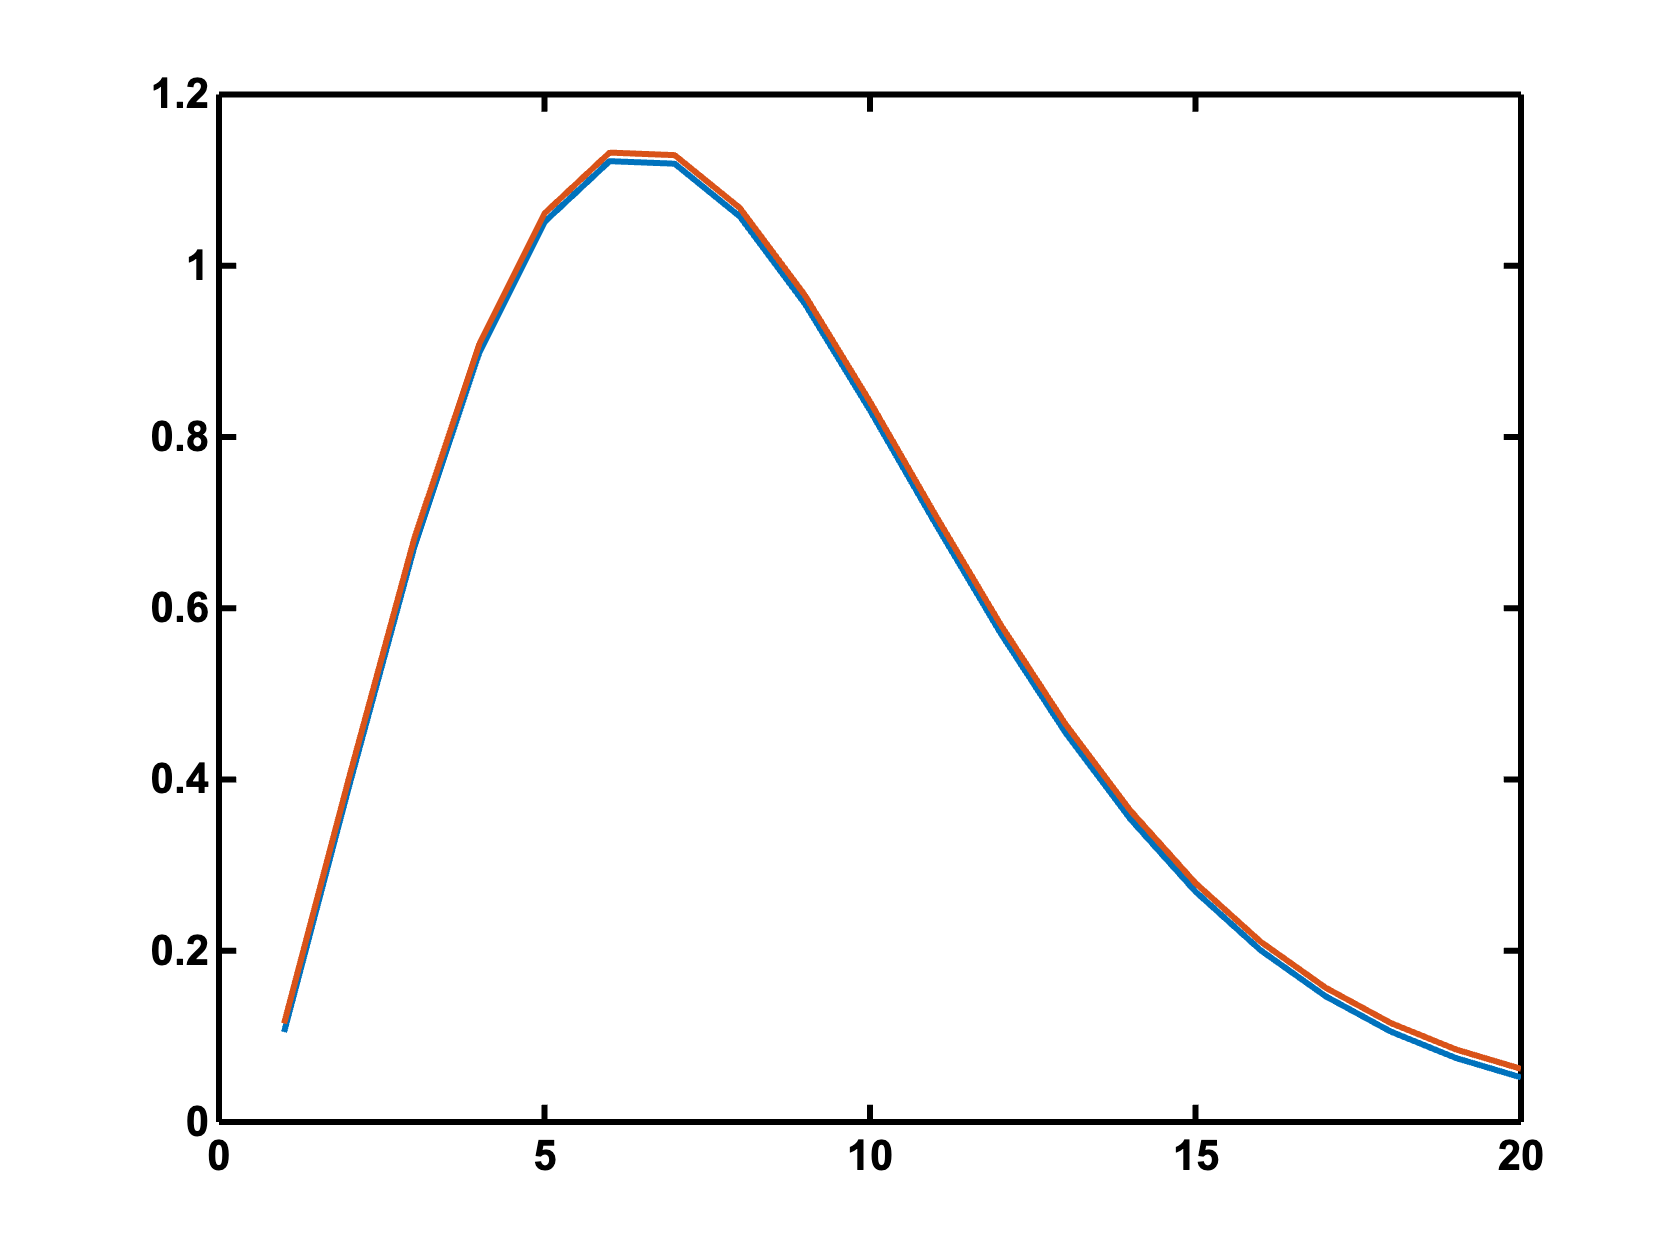

% and now.... drum roll
figure, plot(h), hold on, plot(kernel+0.01)

% in short:
[h] = hrf_est(convolution(1:120)',[3 14 22 36 46 50 66 86 91 106 115], 20); 
plot(h)
